# Neurodata Without Borders Extracellular Electrophysiology Tutorial

## This tutorial

Create fake data for a hypothetical extracellular electrophysiology experiment. The types of data we will convert are:

- Voltage recording

- Local field potential (LFP)

- Spike times

It is recommended to first work through the [Introduction to MatNWB tutorial](https://neurodatawithoutborders.github.io/matnwb/tutorials/html/intro.html), which demonstrates installing MatNWB and creating an NWB file with subject information, animal position, and trials, as well as writing and reading NWB files in MATLAB.

## Setting up the NWB File

An NWB file represents a single session of an experiment. Each file must have a session_description, identifier, and session start time. Create a new [`NWBFile`](https://neurodatawithoutborders.github.io/matnwb/doc/NwbFile.html) object with those and additional metadata. For all MatNWB functions, we use the Matlab method of entering keyword argument pairs, where arguments are entered as name followed by value.

nwb = NwbFile( ...
    'session_description', 'mouse in open exploration',...
    'identifier', 'Mouse5_Day3', ...
    'session_start_time', datetime(2018, 4, 25, 2, 30, 3, 'TimeZone', 'local'), ...
    'timestamps_reference_time', datetime(2018, 4, 25, 3, 0, 45, 'TimeZone', 'local'), ...
    'general_experimenter', 'Last Name, First Name', ... % optional
    'general_session_id', 'session_1234', ... % optional
    'general_institution', 'University of My Institution', ... % optional
    'general_related_publications', {'DOI:10.1016/j.neuron.2016.12.011'}); % optional
nwb

nwb =   NwbFile with properties:

                                nwb_version: '2.2.2'
                           file_create_date: []
                                 identifier: 'Mouse5_Day3'
                        session_description: 'mouse in open exploration'
                         session_start_time: {[2018-04-25T02:30:03.000000+02:00]}
                  timestamps_reference_time: {[2018-04-25T03:00:45.000000+02:00]}
                                acquisition: [0×1 types.untyped.Set]
                                   analysis: [0×1 types.untyped.Set]
                                    general: [0×1 types.untyped.Set]
                    general_data_collection: ''
                            general_devices: [0×1 types.untyped.Set]
             general_experiment_description: ''
                       general_experimenter: 'Last Name, First Name'
                general_extracellular_ephys: [0×1 types.untyped.

## Extracellular Electrophysiology

In order to store extracellular electrophysiology data, you first must create an electrodes table describing the electrodes that generated this data. Extracellular electrodes are stored in an `electrodes` table, which is also a [`DynamicTable`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+hdmf_common/DynamicTable.html). `electrodes` has several required fields: x, y, z, impedence, location, filtering, and electrode_group.

## Electrodes Table

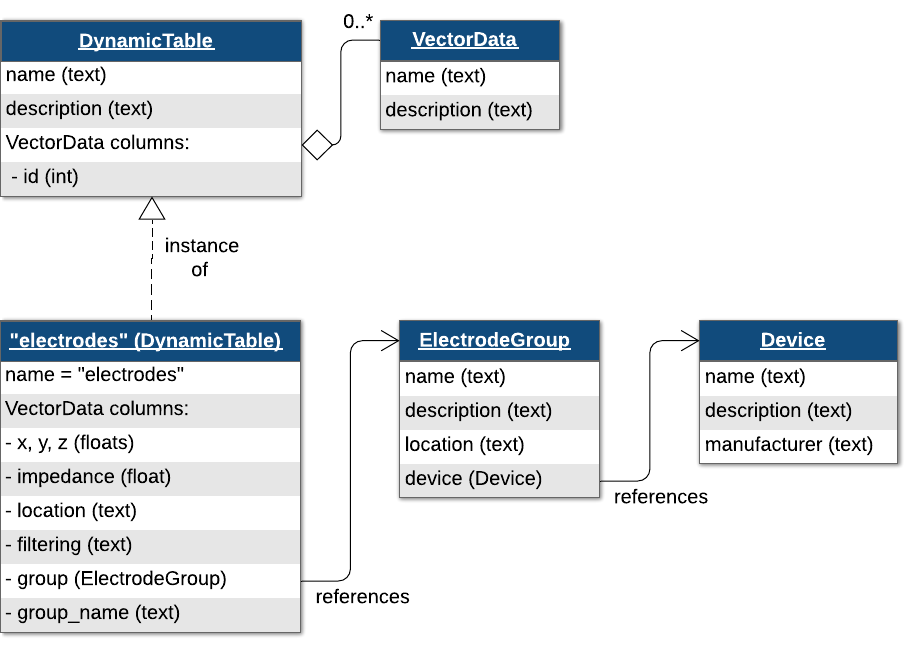

Since this is a [`DynamicTable`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+hdmf_common/DynamicTable.html), we can add additional metadata fields. We will be adding a "label" column to the table.

Here, we also demonstate another method for creating `DynamicTable`s, by first creating a MATLAB native `Table` object and then calling `util.table2nwb` to convert this `Table` object into a [`DynamicTable`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+hdmf_common/DynamicTable.html).

numShanks = 4;
numChannelsPerShank = 3;

ElectrodesDynamicTable = types.hdmf_common.DynamicTable(...
    'colnames', {'location', 'group', 'group_name', 'label'}, ...
    'description', 'all electrodes');

Device = types.core.Device(...
    'description', 'the best array', ...
    'manufacturer', 'Probe Company 9000' ...
);
nwb.general_devices.set('array', Device);
for iShank = 1:numShanks
    shankGroupName = sprintf('shank%d', iShank);
    EGroup = types.core.ElectrodeGroup( ...
        'description', sprintf('electrode group for %s', shankGroupName), ...
        'location', 'brain area', ...
        'device', types.untyped.SoftLink(Device) ...
    );
    
    nwb.general_extracellular_ephys.set(shankGroupName, EGroup);
    for iElectrode = 1:numChannelsPerShank
        ElectrodesDynamicTable.addRow( ...
            'location', 'unknown', ...
            'group', types.untyped.ObjectView(EGroup), ...
            'group_name', shankGroupName, ...
            'label', sprintf('%s-electrode%d', shankGroupName, iElectrode));
    end
end
ElectrodesDynamicTable.toTable()

ans = 12×5 table
    id     location                 group                group_name            label        
    __    ___________    ____________________________    __________    _____________________

     0    {'unknown'}    1×1 types.untyped.ObjectView    {'shank1'}    {'shank1-electrode1'}
     1    {'unknown'}    1×1 types.untyped.ObjectView    {'shank1'}    {'shank1-electrode2'}
     2    {'unknown'}    1×1 types.untyped.ObjectView    {'shank1'}    {'shank1-electrode3'}
     3    {'unknown'}    1×1 types.untyped.ObjectView    {'shank2'}    {'shank2-electrode1'}
     4    {'unknown'}    1×1 types.untyped.ObjectView    {'shank2'}    {'shank2-electrode2'}
     5    {'unknown'}    1×1 types.untyped.ObjectView    {'shank2'}    {'shank2-electrode3'}
     6    {'unknown'}    1×1 types.untyped.ObjectView    {'shank3'} 


nwb.general_extracellular_ephys_electrodes = ElectrodesDynamicTable;

## Links

In the above loop, we create [`ElectrodeGroup`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ElectrodeGroup.html) objects. The `electrodes` table then uses an `ObjectView` in each row to link to the corresponding [`ElectrodeGroup`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ElectrodeGroup.html) object. An `ObjectView` is an object that allow you to create a link from one neurodata type referencing another. 

## ElectricalSeries

Voltage data are stored in [`ElectricalSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ElectricalSeries.html) objects. [`ElectricalSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ElectricalSeries.html) is a subclass of [`TimeSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/TimeSeries.html) specialized for voltage data. In order to create our [`ElectricalSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ElectricalSeries.html) object, we will need to reference a set of rows in the `electrodes` table to indicate which electrodes were recorded. We will do this by creating a [`DynamicTableRegion`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+hdmf_common/DynamicTableRegion.html), which is a type of link that allows you to reference specific rows of a [`DynamicTable`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+hdmf_common/DynamicTable.html), such as the `electrodes` table, by row indices.

Create a [`DynamicTableRegion`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+hdmf_common/DynamicTableRegion.html) that references all rows of the `electrodes` table.

electrode_table_region = types.hdmf_common.DynamicTableRegion( ...
    'table', types.untyped.ObjectView(ElectrodesDynamicTable), ...
    'description', 'all electrodes', ...
    'data', (0:length(ElectrodesDynamicTable.id.data)-1)');

Now create an `ElectricalSeries` object to hold acquisition data collected during the experiment.

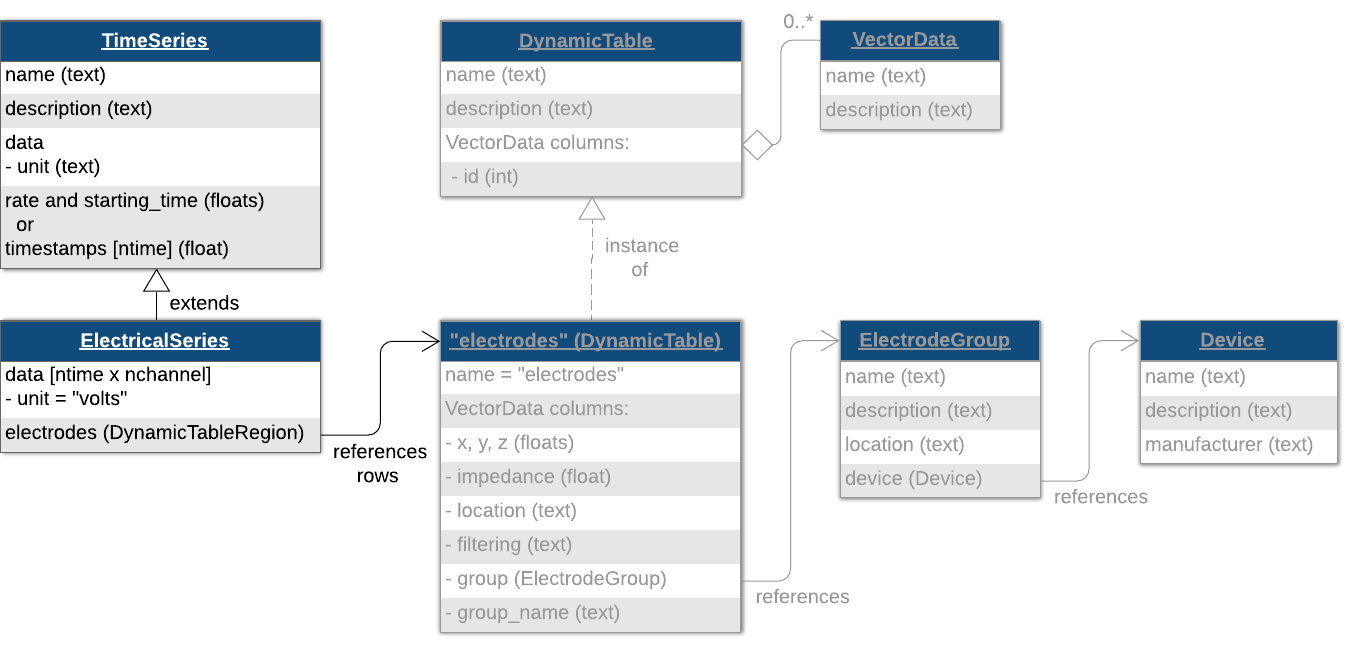

electrical_series = types.core.ElectricalSeries( ...
    'starting_time', 0.0, ... % seconds
    'starting_time_rate', 30000., ... % Hz
    'data', randn(12, 3000), ...
    'electrodes', electrode_table_region, ...
    'data_unit', 'volts');

This is the voltage data recorded directly from our electrodes, so it goes in the acquisition group. 

nwb.acquisition.set('ElectricalSeries', electrical_series);

## LFP

Local field potential (LFP) refers in this case to data that has been downsampled and/or filtered from the original acquisition data and is used to analyze signals in the lower frequency range. Filtered and downsampled LFP data would also be stored in an [`ElectricalSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ElectricalSeries.html). To help data analysis and visualization tools know that this [`ElectricalSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ElectricalSeries.html) object represents LFP data, store it inside an `LFP` object, then place the `LFP` object in a [`ProcessingModule`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ProcessingModule.html) named `'ecephys'`. This is analogous to how we stored the [`SpatialSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/SpatialSeries.html) object inside of a [`Position`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/Position.html) object and stored the [`Position`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/Position.html) object in a [`ProcessingModule`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ProcessingModule.html) named `'behavior'` earlier.

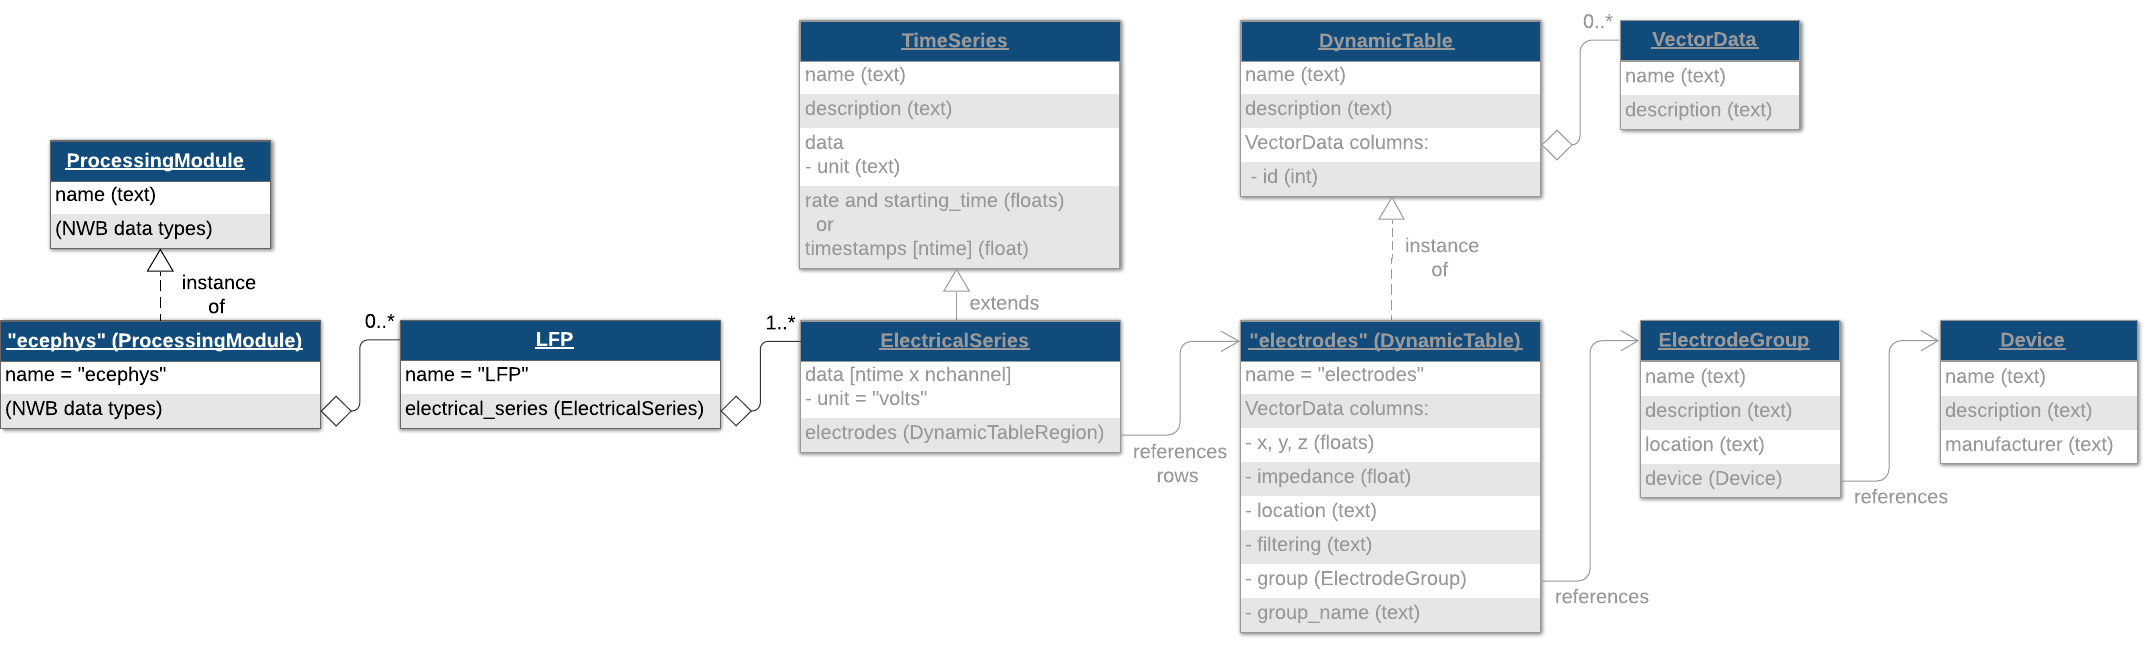

electrical_series = types.core.ElectricalSeries( ...
    'starting_time', 0.0, ... % seconds
    'starting_time_rate', 1000., ... % Hz
    'data', randn(12, 100), ...
    'electrodes', electrode_table_region, ...
    'data_unit', 'volts');

lfp = types.core.LFP('ElectricalSeries', electrical_series);

ecephys_module = types.core.ProcessingModule(...
    'description', 'extracellular electrophysiology');

ecephys_module.nwbdatainterface.set('LFP', lfp);
nwb.processing.set('ecephys', ecephys_module);

## Spike Times

#### Ragged Arrays

Spike times are stored in another [`DynamicTable`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+hdmf_common/DynamicTable.html) of subtype [`Units`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/Units.html). The default `Units` table is at `/units` in the HDF5 file. You can add columns to the [`Units`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/Units.html) table just like you did for `electrodes` and `trials`. Here, we generate some random spike data and populate the table. 

num_cells = 10;
firing_rate = 20;
spikes = cell(1, num_cells);
for iShank = 1:num_cells
    spikes{iShank} = rand(1, randi([16, 28]));
end
spikes

spikes = 1×10 cell array
    {[0.3431 0.3174 0.5544 0.7064 0.2792 0.7972 0.2637 0.0248 0.0595 0.3963 0.3109 0.0193 0.5280 0.2990 0.1221 0.5749 0.1027 0.6968 0.1989 0.8820 0.1922 0.0871 0.5064 0.3728 0.6374 0.9637]}    {[0.9812 0.6313 0.1423 0.2448 0.1009 0.3578 0.4419 0.1541 0.7304 0.6027 0.3662 0.4743 0.3706 0.2829 0.9223 0.2537 0.4682 0.2805 0.0542 0.3164 0.5795 0.7104 0.5881]}    {[0.7818 0.1904 0.2147 0.5979 0.8950 0.0290 0.9357 0.5050 0.9004 0.5580 0.9331 0.0615 0.7271 0.2936 0.7340 0.3191 0.9379 0.7975 0.6499 0.7785 0.1452 0.5669 0.9768 0.8447 0.0410 0.5646]}    {[0.7020 0.9724 0.9332 0.9860 0.4666 0.1261 0.7213 0.4746 0.7565 0.8135 0.0112 0.7259 0.2379 0.7656 0.2754 0.0660 0.7960 0.6297 0.1077 0.7929 0.9414 0.4693 0.0667]}    {[0.9166 0.2519 0.2007 0.4169 0.3550 0.7702 0.1762 0.6321 0.6786 0.0686 0.1624 0.2922 0.3148 0.7203 0.8953 0.3237]}    {[0.2133 0.5296 0.9491 0.5127 0.5308 0.7616 0.9145 0.5420 0.1022 0.2113 0.9846 0.4766 0.3126 0.0991 0.4783 0.7686 0.9528 0.0306 0.1756 0.2

Spike times are an example of a ragged array- it's like a matrix, but each row has a different number of elements. We can represent this type of data as an indexed column of the units [`DynamicTable`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+hdmf_common/DynamicTable.html). These indexed columns have two components, the vector data object that holds the data and the vector index object that holds the indices in the vector that indicate the row breaks. You can use the convenience function `util.create_indexed_column` to create these objects.

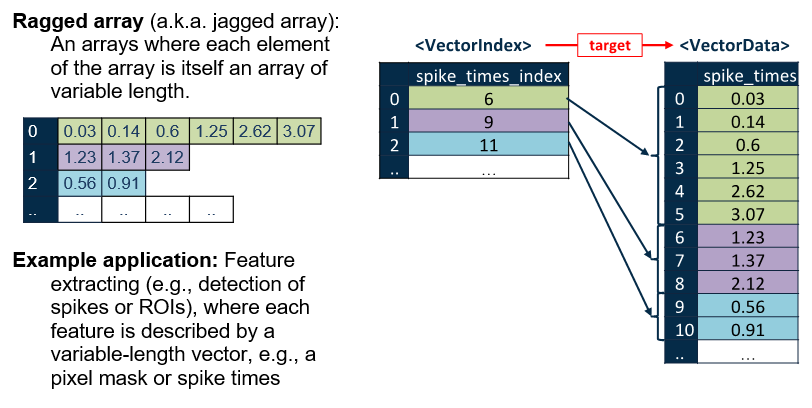

[spike_times_vector, spike_times_index] = util.create_indexed_column(spikes);


nwb.units = types.core.Units( ...
    'colnames', {'spike_times'}, ...
    'description', 'units table', ...
    'spike_times', spike_times_vector, ...
    'spike_times_index', spike_times_index ...
);

## Designating Electrophysiology Data

As mentioned above, [`ElectricalSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ElectricalSeries.html) objects are meant for storing specific types of extracellular recordings. In addition to this [`TimeSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/TimeSeries.html) class, NWB provides some [Processing Modules](https://pynwb.readthedocs.io/en/stable/tutorials/general/plot_file.html#modules-overview) for designating the type of data you are storing. We will briefly discuss them here, and refer the reader to the [**API documentation**](https://neurodatawithoutborders.github.io/matnwb/doc/index.html) and [**Intro to NWB**](https://neurodatawithoutborders.github.io/matnwb/tutorials/html/intro.html) for more details on using these objects.

For storing spike data, there are two options. Which one you choose depends on what data you have available. If you need to store complete and/or continuous raw voltage traces, you should store the traces with [`ElectricalSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ElectricalSeries.html) objects as acquisition data, and use the [`EventDetection`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/EventDetection.html) class for identifying the spike events in your raw traces. If you do not want to store the raw voltage traces and only the waveform ‘snippets’ surrounding spike events, you should use the [`EventWaveform`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/EventWaveform.html) class, which can store one or more [`SpikeEventSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/SpikeEventSeries.html) objects.

The results of spike sorting (or clustering) should be stored in the top-level [`Units`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/Units.html) table. Note that it is not required to store spike waveforms in order to store spike events or mean waveforms–if you only want to store the spike times of clustered units you can use only the [`Units`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/Units.html) table.

For local field potential data, there are two options. Again, which one you choose depends on what data you have available. With both options, you should store your traces with [`ElectricalSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ElectricalSeries.html) objects. If you are storing unfiltered local field potential data, you should store the [`ElectricalSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ElectricalSeries.html) objects in [`LFP`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/LFP.html) data interface object(s). If you have filtered LFP data, you should store the [`ElectricalSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ElectricalSeries.html) objects in [`FilteredEphys`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/FilteredEphys.html) data interface object(s).

## Writing the NWB File

nwbExport(nwb, 'ecephys_tutorial.nwb')

## Reading NWB Data

Data arrays are read passively from the file. Calling `TimeSeries.data` does not read the data values, but presents an HDF5 object that can be indexed to read data. This allows you to conveniently work with datasets that are too large to fit in RAM all at once. `load` with no input arguments reads the entire dataset:

nwb2 = nwbRead('ecephys_tutorial.nwb', 'ignorecache');
nwb2.processing.get('ecephys'). ...
    nwbdatainterface.get('LFP'). ...
    electricalseries.get('ElectricalSeries'). ...
    data.load;

## Accessing Data Regions

If all you need is a data region, you can index a `DataStub` object like you would any normal array in MATLAB, as shown below. When indexing the dataset this way, only the selected region is read from disk into RAM. This allows you to handle very large datasets that would not fit entirely into RAM.

% read section of LFP
nwb2.processing.get('ecephys'). ...
    nwbdatainterface.get('LFP'). ...
    electricalseries.get('ElectricalSeries'). ...
    data(1:5, 1:10)

ans =    -0.9466   -0.2022    2.0076    1.7712   -0.7082    0.7048    0.6486   -0.2986    1.4553   -0.2157
   -0.0102   -1.3299    0.3175    0.4905    0.0754   -0.4104   -0.5911   -0.9635   -1.9110   -0.9900
   -1.0205   -1.1092   -0.7455    1.7710    0.3532   -0.6344    1.7988    0.2843    0.1212   -0.5827
   -1.5592    0.0287   -0.7516    0.8773   -0.6986   -0.3571    1.8583   -1.1203    0.8597   -0.3262
    0.4979   -1.0507    0.3918    0.8403   -0.1060   -1.4502    1.4192    0.2729   -0.4680   -0.1500



% You can use the getRow method of the table to load spike times of a specific unit.
% To get the values, unpack from the returned table.
nwb.units.getRow(1).spike_times{1}

ans =     0.3431
    0.3174
    0.5544
    0.7064
    0.2792
    0.7972
    0.2637
    0.0248
    0.0595
    0.3963


# Learn more!

### See the [API documentation](https://neurodatawithoutborders.github.io/matnwb/doc/index.html) to learn what data types are available.

## MATLAB tutorials

- [Optical physiology](https://neurodatawithoutborders.github.io/matnwb/tutorials/html/ophys.html)

- [Intracellular electrophysiology](https://neurodatawithoutborders.github.io/matnwb/tutorials/html/icephys.html)

## Python tutorials

See our tutorials for more details about your data type:

- [Calcium imaging](https://pynwb.readthedocs.io/en/stable/tutorials/domain/ophys.html#sphx-glr-tutorials-domain-ophys-py)

- [Extracellular electrophysiology](https://pynwb.readthedocs.io/en/stable/tutorials/domain/ecephys.html#sphx-glr-tutorials-domain-ecephys-py)

- [Intracellular electrophysiology](https://pynwb.readthedocs.io/en/stable/tutorials/domain/icephys.html#sphx-glr-tutorials-domain-icephys-py)

**Check out other tutorials that teach advanced NWB topics:**

- [Iterative data write](https://pynwb.readthedocs.io/en/stable/tutorials/general/iterative_write.html#sphx-glr-tutorials-general-iterative-write-py)

- [Extensions](https://pynwb.readthedocs.io/en/stable/tutorials/general/extensions.html#sphx-glr-tutorials-general-extensions-py)

- [Advanced HDF5 I/O](https://pynwb.readthedocs.io/en/stable/tutorials/general/advanced_hdf5_io.html#sphx-glr-tutorials-general-advanced-hdf5-io-py)